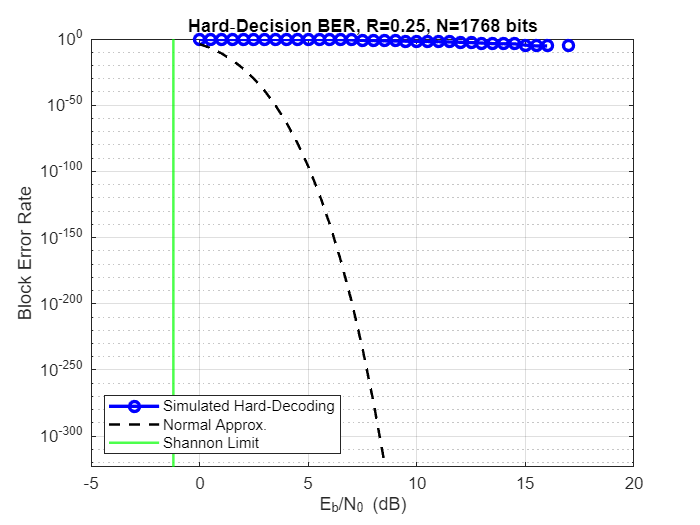

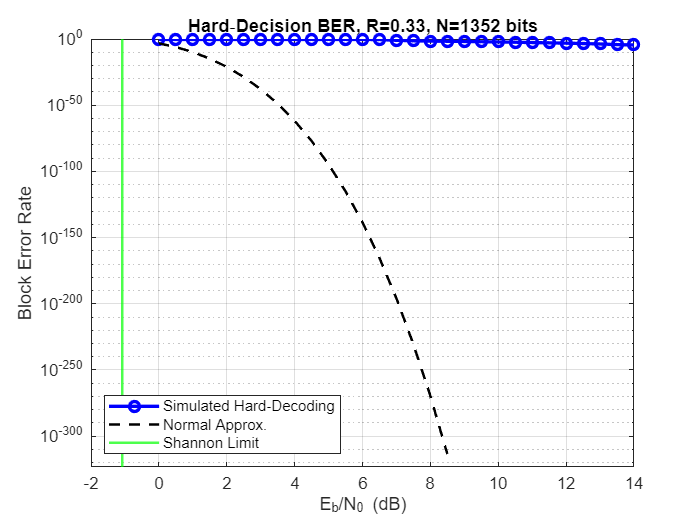

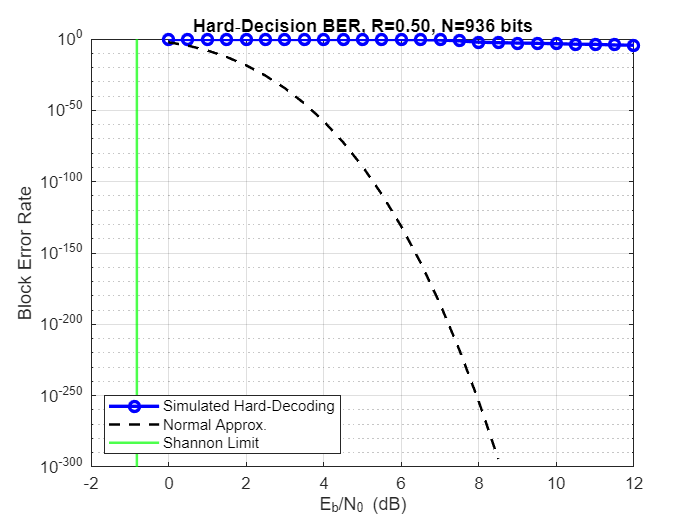

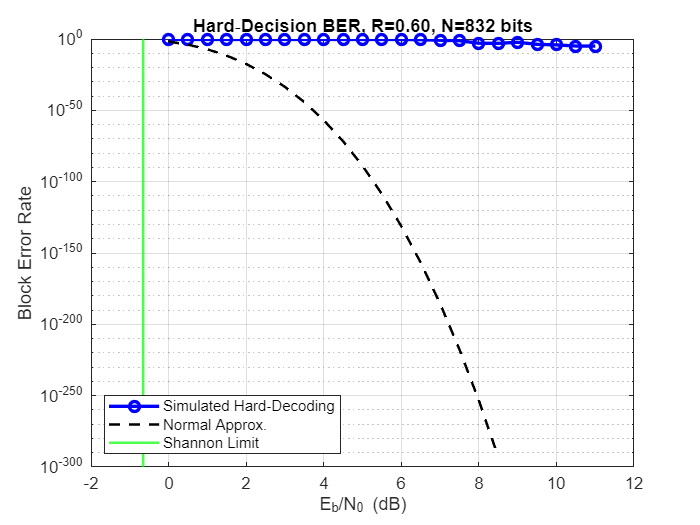

clear; clc;

baseGraph     = 'NR_2_6_52';
codeRates     = [1/4, 1/3, 1/2, 3/5];
EbN0dBList    = 0:0.5:30;
numTrials     = 100;
maxIterations = 20;

[B, Hfull, z] = nrldpc_Hmatrix(baseGraph);
[mb, nb]      = size(B);

Rcount     = length(codeRates);
Ecount     = numel(EbN0dBList);
decErr     = zeros(Rcount, Ecount);
probSucc   = zeros(Rcount, Ecount);
blockLen   = zeros(1, Rcount);

for rIdx = 1:Rcount
    rate = codeRates(rIdx);
    
    [H, Nbits]      = H_matrix(Hfull, z, mb, nb, rate);
    blockLen(rIdx)  = Nbits;
    
    c2v_map = get_c2v(H);
    v2c_map = get_v2c(H);

    for eIdx = 1:Ecount
        EbN0dB = EbN0dBList(eIdx);
        
        for tr = 1:numTrials
           
            msg = randi([0,1], (nb-mb)*z, 1);
            cw  = encodeLDPC(B, z, msg, Nbits);
            
            tx = 1 - 2*cw;
            rx = addAWGN(tx, rate, EbN0dB);

            [decBits, success] = hardDecoding(H, rx, maxIterations, c2v_map, v2c_map);

            decErr(rIdx,eIdx)   = decErr(rIdx,eIdx)   + bitErrorRate(cw, decBits);
            probSucc(rIdx,eIdx) = probSucc(rIdx,eIdx) + success;
        end
        
        decErr(rIdx,eIdx)   = decErr(rIdx,eIdx)   / numTrials;
        probSucc(rIdx,eIdx) = probSucc(rIdx,eIdx) / numTrials;
    end
end

for i = 1:Rcount
    rate = codeRates(i);
    N    = blockLen(i);
    
    gammaLin  = 10.^(EbN0dBList/10);
    P         = rate .* gammaLin;
    C         = log2(1 + P);
    V         = (log2(exp(1))).^2 .* P .* (P+2) ./ (P+1).^2;
    arg       = sqrt(N) .* ( C - rate + log2(N)./(2*N) ) ./ sqrt(V);
    PN_e      = 0.5 * erfc(arg./sqrt(2));  % Q(x) = 0.5·erfc(x/√2)

    EbN0_sh = 10*log10((2^rate - 1)/rate);
    
    figure;
    semilogy(EbN0dBList, decErr(i,:), 'b-o','LineWidth',2); hold on;
    semilogy(EbN0dBList, PN_e, 'k--','LineWidth',1.5);
    xline(EbN0_sh, 'g-','LineWidth',1.5);
    grid on;
    xlabel('E_b/N_0 (dB)');
    ylabel('Block Error Rate');
    title (sprintf('Hard‑Decision BER, R=%.2f, N=%d bits', rate, N));
    legend('Simulated Hard‑Decoding','Normal Approx.','Shannon Limit','Location','southwest');
end

function [decoded, success] = hardDecoding(H, rx, maxIter, c2v_map, v2c_map)
   
    nVars   = size(H,2);
    decoded = rx < 0;
    prev    = decoded;
    success = false;

    v2c_msgs = zeros(size(H));
    for vn = 1:nVars
        for cn = v2c_map{vn}
            v2c_msgs(cn,vn) = decoded(vn);
        end
    end

    for iter = 1:maxIter
       
        c2v_msgs = zeros(size(H));
        for cn = 1:numel(c2v_map)
            vs = c2v_map{cn};
            xor_all = 0;
            for v = vs, xor_all = xor(xor_all, v2c_msgs(cn,v)); end
            for v = vs
                c2v_msgs(cn,v) = xor(xor_all, v2c_msgs(cn,v));
            end
        end

        new_est = zeros(nVars,1);
        for vn = 1:nVars
            cs = v2c_map{vn};
            dv = numel(cs);
            totalOnes = decoded(vn) + sum(c2v_msgs(cs,vn));
            for cn = cs
                excl = totalOnes - c2v_msgs(cn,vn);
                v2c_msgs(cn,vn) = excl > dv/2;
            end
            new_est(vn) = totalOnes > floor(dv/2);
        end

        if all(mod(H*new_est,2)==0)
            decoded = new_est;
            success = true;
            return
        end
        if isequal(new_est, prev)
            decoded = new_est;
            return
        end
        prev    = new_est;
        decoded = new_est;
    end
end

function rx = addAWGN(tx, rate, EbN0dB)
    gamma = 10^(EbN0dB/10);
    sigma = sqrt(1/(2*rate*gamma));
    rx    = tx + sigma*randn(size(tx));
end

function [H, Nbits] = H_matrix(Hfull, z, mb, nb, rate)
    parityCols = (nb-mb) - 2;
    nbRM       = min( ceil(parityCols/rate)+2, nb );
    Nbits      = nbRM * z;
    Htrunc     = Hfull(:,1:Nbits);
    chkRows    = mb*z - nb*z + Nbits;
    H          = Htrunc(1:chkRows,:);
end

function c = encodeLDPC(B, z, msg, Nbits)
    cw_full = nrldpc_encode(B, z, msg');
    c       = cw_full(1:Nbits)';
end

function ber = bitErrorRate(orig, dec)
    ber = sum(xor(orig,dec)) / numel(orig);
end

function c2v = get_c2v(H)
    for i = 1:size(H,1)
        c2v{i} = find(H(i,:));
    end
end

function v2c = get_v2c(H)
    for j = 1:size(H,2)
        v2c{j} = find(H(:,j))';
    end
end

function [B, H, z] = nrldpc_Hmatrix(BG)
    % load base‑graph and expand
    load(sprintf('%s.txt',BG),BG);
    B   = eval(BG);
    [mb,nb] = size(B);
    z   = max(B(:)) + 1;
    Iz  = eye(z); I0 = zeros(z);
    H   = zeros(mb*z, nb*z);
    for ii=1:mb
        rows = (ii-1)*z + (1:z);
        for jj=1:nb
            cols = (jj-1)*z + (1:z);
            if B(ii,jj)==-1
                H(rows,cols)=I0;
            else
                H(rows,cols)=circshift(Iz,-B(ii,jj));
            end
        end
    end
end

function y = mul_sh(x,k)
    if k==-1
        y = zeros(1,length(x));
    else
        y = [x(k+1:end), x(1:k)];
    end
end

function cw = nrldpc_encode(B, z, msg)
    [m,n] = size(B);
    cw    = zeros(1,n*z);
    cw(1:(n-m)*z) = msg;
    temp = zeros(1,z);
    for i=1:4
        for j=1:(n-m)
            temp = mod(temp + mul_sh(msg((j-1)*z+1:j*z), B(i,j)),2);
        end
    end
    if B(2,n-m+1)==-1, p=B(3,n-m+1); else p=B(2,n-m+1); end
    cw((n-m)*z+1:(n-m+1)*z) = mul_sh(temp, z-p);
    for i=1:3
        temp = zeros(1,z);
        for j=1:(n-m+i)
            temp = mod(temp + mul_sh(cw((j-1)*z+1:j*z), B(i,j)),2);
        end
        cw((n-m+i)*z+1:(n-m+i+1)*z) = temp;
    end
    for i=5:m
        temp = zeros(1,z);
        for j=1:(n-m+4)
            temp = mod(temp + mul_sh(cw((j-1)*z+1:j*z), B(i,j)),2);
        end
        cw((n-m+i-1)*z+1:(n-m+i)*z) = temp;
    end
end
